% activity knn
clear
load hapt.mat
[training, test] = hapt_activity(hapt);
hapt_knn(training, test, 1);
disp(ans);

% activity knn after lda to 10 dimensions
clear
load hapt.mat
[training, test] = hapt_activity_lda(hapt, 10);
hapt_knn(training, test, 1);
disp(ans);

    0.9007



% cross validating hyperparameters for activity knn
% sit down for this one
clear
load hapt.mat

roc = [];

for L = [1, 10, 25, 50, 100, 250, 500, 561]
    [training, test] = hapt_activity_lda(hapt, L);
    for K = [1, 2, 5, 10, 25, 50]
        [tpr, fpr] = hapt_knn(training, test, K);
        roc = [roc; tpr, fpr, L, K];
    end

    0.7003



end
plot(1-roc(:,1), 1-roc(:,2));

% subject knn
clear

training =     X: [3638×561 double]
    Y: [3638×1 double]


test =     X: [1553×561 double]
    Y: [1553×1 double]


Index exceeds matrix dimensions.

Error in slinfsgd (line 49)
            XB=J(((jj-1)*B+1):jj*B,:);YB=Yj(((jj-1)*B+1):jj*B,:);


load hapt.mat
[training, validation, test] = hapt_subject(hapt);
hapt_knn(training, test, 1);
disp(ans);

% subject knn after lda to 30 dimensions
clear
load hapt.mat
[training, validation, test] = hapt_subject_lda(hapt, 30);
hapt_knn(training, test, 1);
disp(ans);

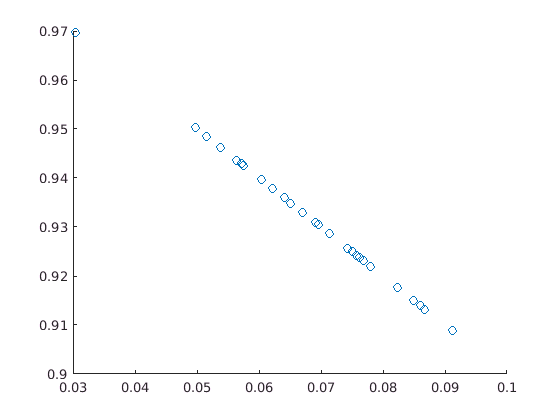

% cross validating hyperparameters for subject knn
% sit down for this one
clear

load hapt.mat

roc = [];

for L = [1, 10, 25, 50, 100, 250, 500, 561]
    [training, test] = hapt_subject_lda(hapt, L);
    for K = [1, 2, 5, 10, 25, 50]
        [tpr, fpr] = hapt_knn(training, test, K);
        roc = [roc; tpr, fpr, L, K];
    end
end
plot(1-roc(:,1), 1-roc(:,2));


% subject binary (is specific subject or not) with knn and lda to 10 dimensions
clear
load hapt.mat


Error using eig
For generalized eigenproblem EIG(A,B), A and B must be the same size.

Error in lda (line 49)
    [Ev, Ed] = eig( bcSM, twcSM );

Error in hapt_subject_binary_lda (line 4)
    [~,Sw,~,Sb,U,~,J] = lda(training.X, training.Y);

roc = [];

for subject = 1:30
    [training, test] = hapt_subject_binary_lda(hapt, 10, subject);
    [tpr, fpr] = hapt_knn(training, test, 1);
    roc = [roc; tpr, fpr, subject];
end

    0.9987



disp(mean(roc(:,1)));
disp('frighteningly high accuracy');

% subject binary knn cross validation
% lay down for this one
clear
load hapt.mat

roc = [];


    0.8931



for subject = 1:30
    for L = [1, 10, 25, 50, 100, 250, 500, 561]
        [training, test] = hapt_subject_binary_lda(hapt, L, subject);
        for K = [1, 2, 5, 10, 25, 50]
            [tpr, fpr] = hapt_knn(training, test, K);
            roc = [roc; tpr, fpr, L, K, subject];
        end
    end
end
plot(roc(:,2), roc(:,1));


% activity binary knn after lda to single dimension
clear

    0.8931



load hapt.mat
[training, test] = hapt_activity_binary_lda(hapt, 1);
hapt_knn(training, test, 1);
disp(ans);

% activity binary logregr with sgd after lda to 2 dimensions
load hapt.mat

[training, test] = hapt_activity_binary_lda(hapt, 2);

g0.W = randn(1,size(training.X,2))/1e3; g0.w = randn/1e3; g0.type = 'slinf';
hapt_logregr(training, test, 1, 0.1, 10, 1819, g0);
disp(ans);

%
load hapt.mat


subject = 1;
    [training, test] = hapt_subject_binary_lda(hapt, 2, subject);
    [tpr, fpr] = hapt_linsvm(training, test, 1, 1);


